# Non linear ODE

## Initialization of MATLAB

clear; close all;clc
AR = 1.618;
width = 20; height = width/AR;

## Problem Definition


$$u_t = -u u_x, \quad x \in [0,1], t>0\\
u(x = 0) = u(x = 1) = 0; u(x,0) = \sin(\pi x/L)$$


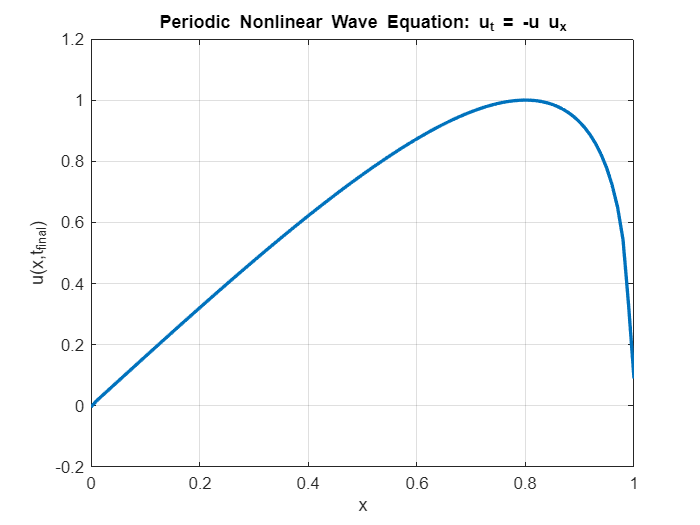

% FOM
L = 1; Nx = 100; x = linspace(0,L,Nx); dx = x(2)-x(1);
t = 0.3; dt = 1e-4; Nt = length(0:dt:t);
u = zeros(Nx,Nt); u(:,1) = sin(pi.*x/L);
e = ones(Nx,1);
D1 = spdiags([-0.5*e 0.5*e], [-1 1], Nx, Nx) / dx;
rhs = @(u) -D1*(u.^2./2);
for n = 1:Nt
    k1 = rhs(u(:,n));
    k2 = rhs(u(:,n) + 0.5*dt*k1);
    k3 = rhs(u(:,n) + 0.5*dt*k2);
    k4 = rhs(u(:,n) + dt*k3);
    u(:,n+1) = u(:,n) + (dt/6)*(k1 + 2*k2 + 2*k3 + k4);
end
% Plot
figure('Color','w');
plot(x, u(:,end), 'LineWidth', 2);
xlabel('x'); ylabel('u(x,t_{final})');
title('Periodic Nonlinear Wave Equation: u_t = -u u_x');
grid on;

## ROM

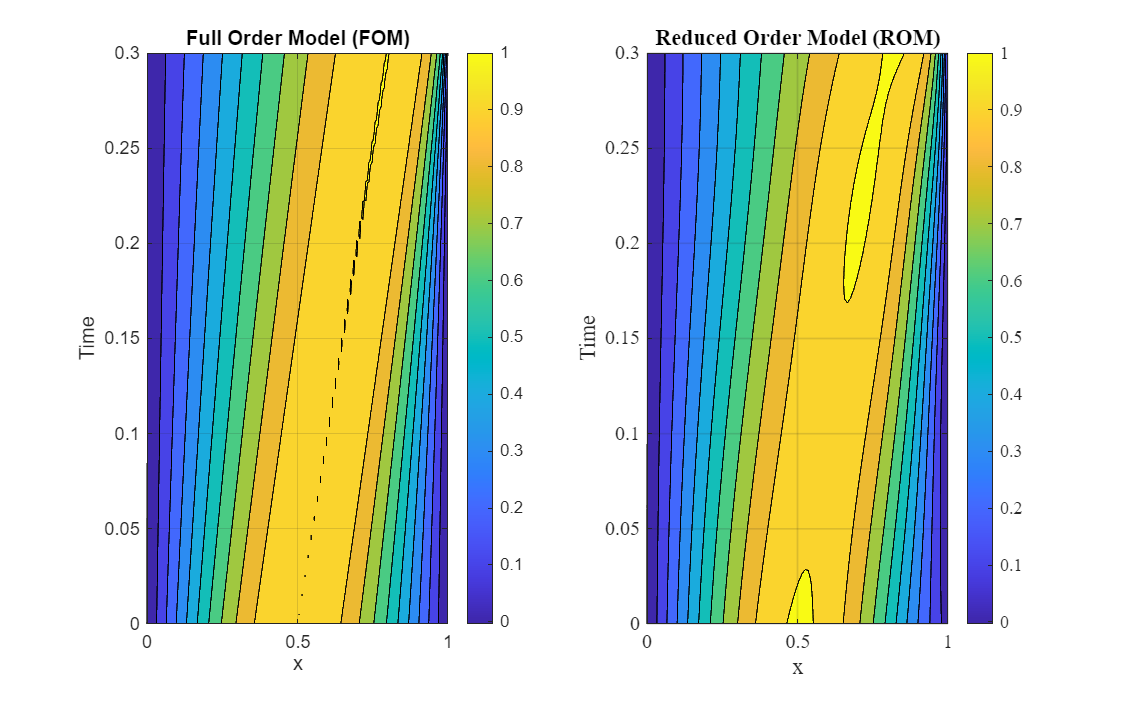

[Uu,Su,~]= svd(u,'econ');
cumEu = cumsum(diag(Su).^2) / sum(diag(Su).^2);
ru= find(cumEu>= 0.9999, 1);
Uu = Uu(:,1:ru);
rhs = @(u) -D1*(u.^2./2);
N = zeros(Nx,Nt);
for i = 1:Nt
    N(:,i) = rhs(u(:,i)); % Non linear snapshot matrix
end
[UN,SN,~] = svd(N,"econ");
cumEN = cumsum(diag(SN).^2) / sum(diag(SN).^2);
rN= find(cumEN>= 0.99, 1);
UN = UN(:,1:rN);
[P,~] = deim(UN);

NHat = UN*pinv(P'*UN)*P'*N; % DEIM Approximation of nonlinear operator (no error)
W = Uu'*UN*pinv(P'*UN)*P'; % Precomputed values

uRec = zeros(ru,Nt); uRec(:,1) = Uu'*u(:,1);
rhs = @(uRec) -W*((D1*((Uu*uRec).^2./2)));
for n = 1:Nt
    k1 = rhs(uRec(:,n));
    k2 = rhs(uRec(:,n) + 0.5*dt*k1);
    k3 = rhs(uRec(:,n) + 0.5*dt*k2);
    k4 = rhs(uRec(:,n) + dt*k3);
    uRec(:,n+1) = uRec(:,n) + (dt/6)*(k1 + 2*k2 + 2*k3 + k4);
end
uRec = Uu*uRec;
%% Comparison between FOM and ROM
tspan = 0:dt:t;

% --- Plot FOM vs ROM surface ---
figure('Color','w','Position',[200 200 1000 400])

subplot(1,2,1)
contourf(x, tspan, u(:,1:end-1)')
xlabel('x','FontSize',16)
ylabel('Time','FontSize',16)
zlabel('u(x,t)','FontSize',16)
title('Full Order Model (FOM)','FontSize',16,'FontWeight','bold')
colorbar
grid on
set(gca,'FontSize',11)

subplot(1,2,2)
contourf(x, tspan, uRec(:,1:end-1)')
xlabel('x')
ylabel('Time')
zlabel('u_{ROM}(x,t)')
title('Reduced Order Model (ROM)')
colorbar
grid on;
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12, 'LineWidth', 1);
set(gcf, 'Units', 'centimeters', 'Position', [2 2 width*1.2 height*1.2]);
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperSize', [width*1.2 height*1.2]);
set(gcf, 'PaperPosition', [0 0 width*1.2 height*1.2]);
set(gcf, 'PaperPositionMode', 'manual');
print(gcf, 'Plots/R5f1.pdf', '-dpdf', '-r300');

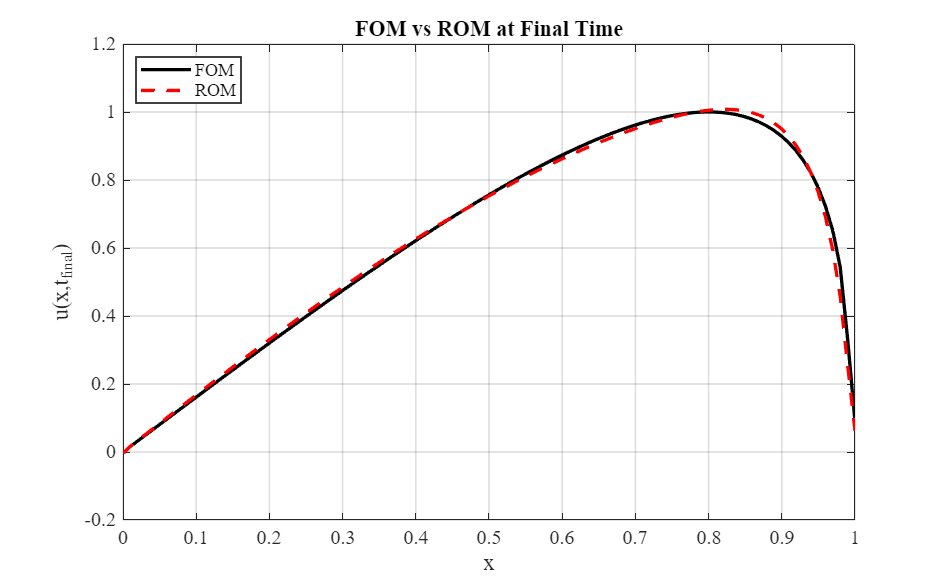


% --- Plot final time snapshot ---
figure('Color','w','Position',[300 300 700 400])
plot(x, u(:,end), 'k-', 'LineWidth',2.0); hold on;
plot(x, uRec(:,end), 'r--', 'LineWidth',2.0);
xlabel('x')
ylabel('u(x,t_{final})')
title('FOM vs ROM at Final Time')
legend({'FOM','ROM'},'Location','northwest')
grid on
box on
grid on;
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12, 'LineWidth', 1);
set(gcf, 'Units', 'centimeters', 'Position', [2 2 width height]);
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperSize', [width height]);
set(gcf, 'PaperPosition', [0 0 width height]);
set(gcf, 'PaperPositionMode', 'manual');
print(gcf, 'Plots/R5f2.pdf', '-dpdf', '-r300');

% --- Error display ---
error_val = (norm(u,'fro')-norm(uRec,'fro'))*100/norm(uRec,'fro');
disp(['Relative Frobenius norm difference = ', num2str(error_val, '%.3f'), '%'])

Relative Frobenius norm difference = 0.070%
